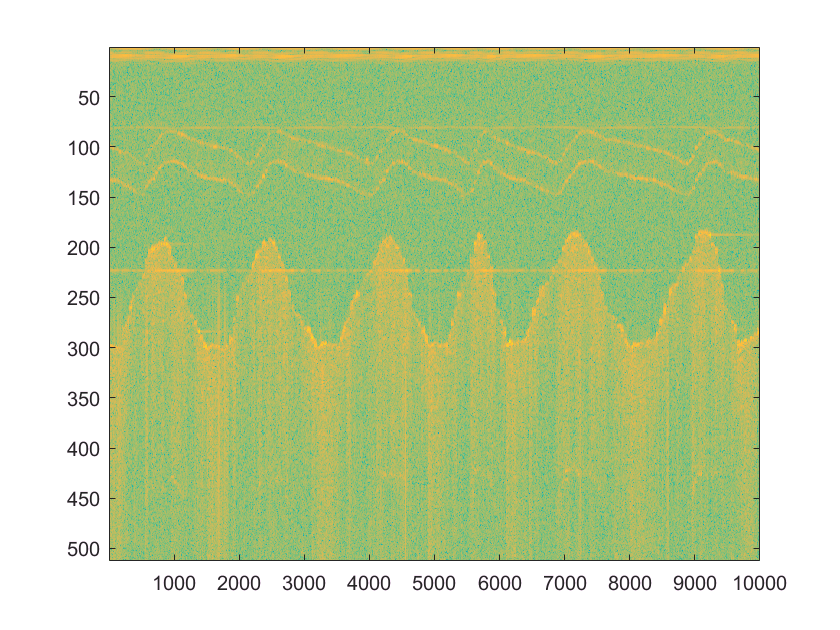

disp(filename);
% f=fopen('09052017034909__ascan_3.bin')
% B=fread(f,'float32');

% close all
% clear all
% filename = '09052017034909__ascan_3.bin';
% filehandle = fopen(filename);
% B=fread(filehandle,'float32');
C=original;

figure('name','Ascans')
imagesc(C)

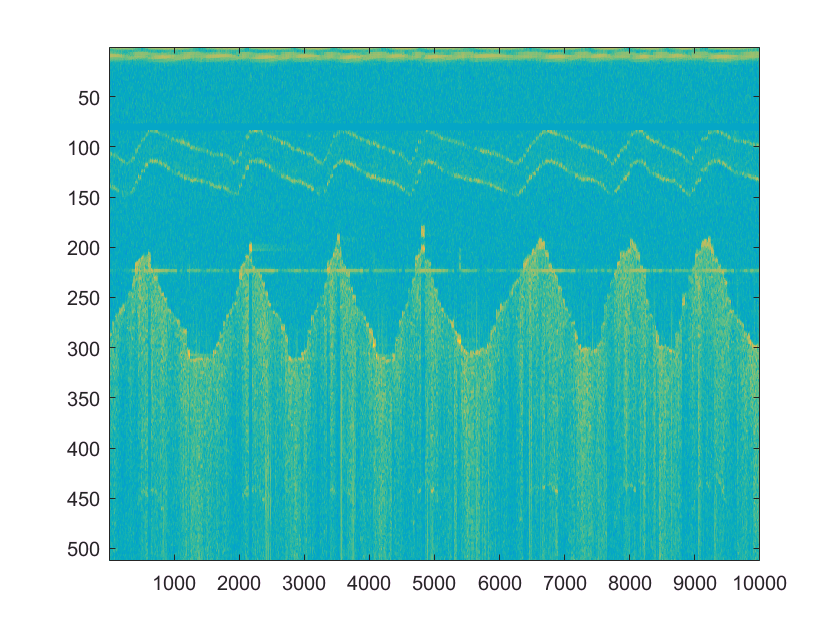


%Linien entfernen 
C(78:83,:)=35/CMAX;

%Medianfilter/Kantenfilter (es wird nur ein Ausschnitt aus der Matrix betrachtet)
C1=medfilt2(C);
figure('name','Ascan Medianfilter')
imagesc(C1)

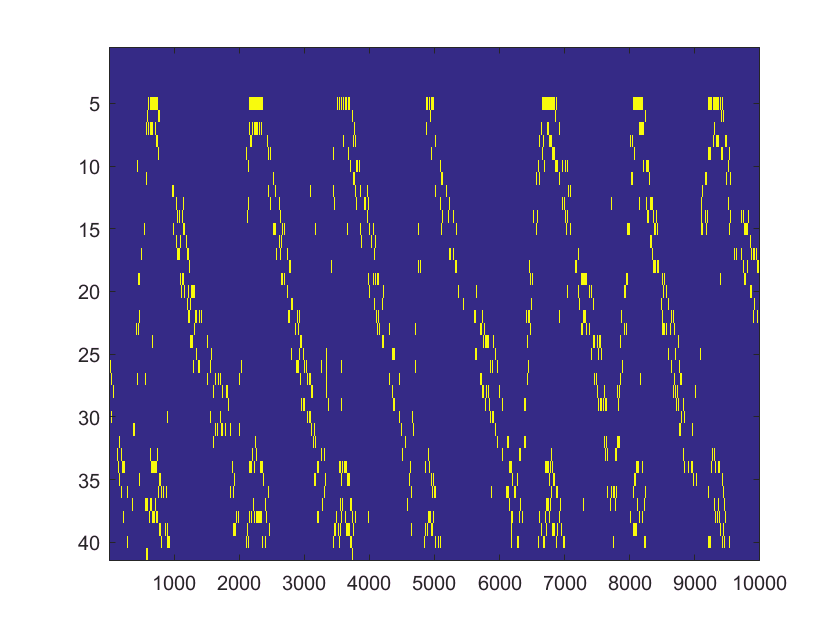

C2=C1(80:120,:);
[BW,thresh]= edge(C2,'Prewitt');

figure('name','kantengefiltert')
imagesc(BW)

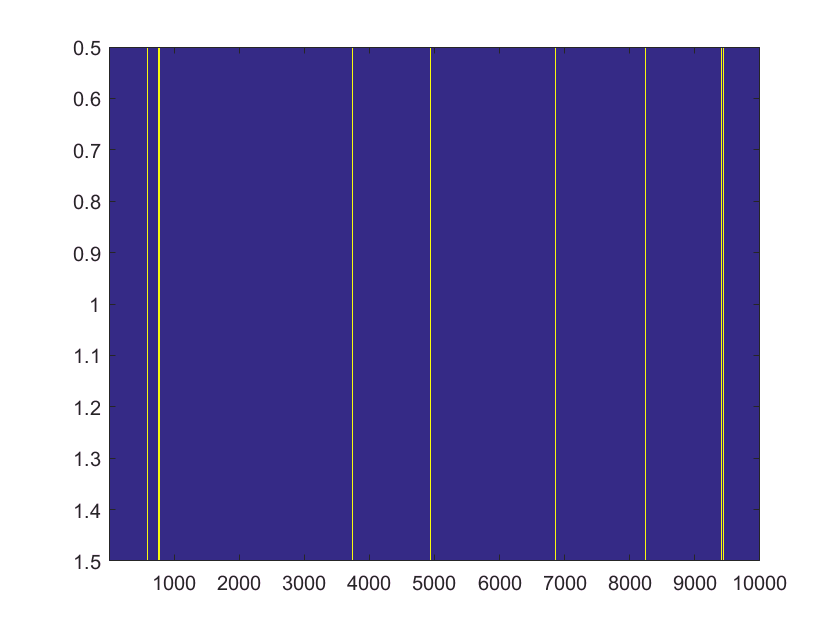


%Gelbe Punkte auf einer Linie werden gesucht
for i=4:6
    for k=1:10000
   if BW(i,k)==1
    x(k)=1; 
   else 
       x(k)=0;
   end 
    end 
end 


%figure('name','Bereiche der Maxima')
%imagesc(x)






eins=0;
anz_eins=0;
werte_eins=0;

%Abstände der gefundenen Punkte werden ermittelt
for i = 1:10000 
    if(x(i)==1)
        anz_eins=anz_eins+1; 
        werte_eins(anz_eins)=eins+1; 
        eins = 1; 
    else
        eins = eins+1; 
    end
end

werte_zwei(:)=werte_eins(:);

%kleine Abstände werden vernachlässigt
for i=2:anz_eins-1
    if werte_eins(i)<=1000
        werte_eins(i+1)=werte_eins(i+1)+werte_eins(i);
        werte_eins(i)=0;
    end 
end 

Max=0;
anz_Max=0;

for i = 1:anz_eins
    if(werte_eins(i)~=0)
anz_Max=anz_Max+1; 
werte_Max(anz_Max)=werte_eins(i); 
    end
end

figure('name','Schnittstellen')
imagesc(C)
hold on 

werte_MaxMax(1)=werte_zwei(1);
for i=1:anz_Max-1
werte_MaxMax(i+1)=werte_Max(i+1)+werte_MaxMax(i);
end 

A = 80*ones(anz_Max-1,1);

A =     80
    80
    80
    80
    80
    80
    80


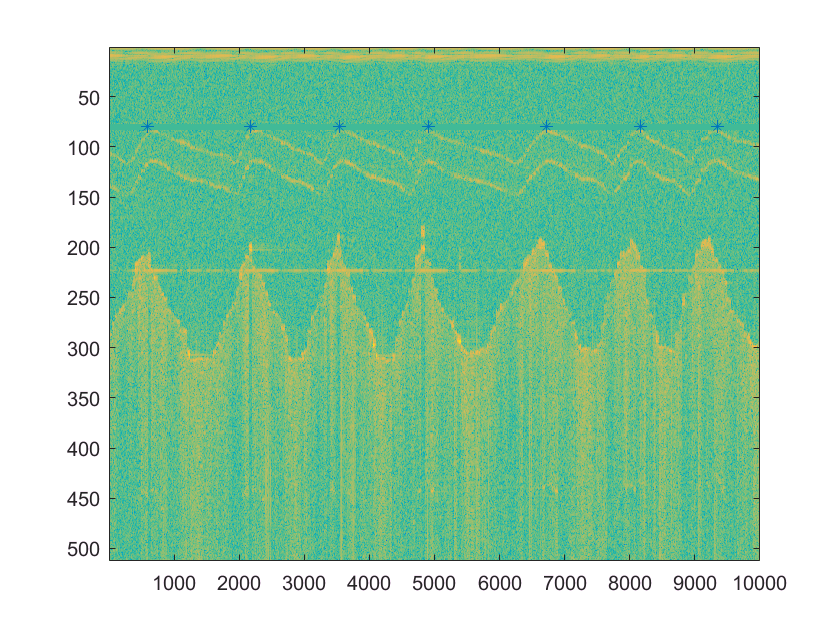

plot(werte_MaxMax(1:end-1),A,'*')